% SI_Model
% This model for teh spread of a disease is dependent
% on the state variables S and I

## Preparación del modelo en simulink

clear all;clc
model='Simulink_Ebola';% nombre del modelo
ParIn={'V0','Beta','Delta','P','C','u'}; %nombres de los parámetros (tal y como aparecen en la máscara del sistema)
Ranges=[0.9 1.2; 1.78e-7 2e-7; 1e-3 1e-2; 338 418; 7.5 8.5; 500 500]; % Rangos para los parámetros
out_names={'Susceptible','Infected','Virus'};%nombres de las salidas del modelo
[T,time] = gsua_dataprep(model,Ranges,ParIn,'out_names',out_names)%Creación de la tabla que controla el sistema
%rho = 0.001;             %cell death rate
%beta = 1.91e-6;          % effective infection rate
%delta = 1e-3;            %infected cell death rate
%c = 8.02; %1/day         %viral clearance rate of Ebola
%p = 378;                 %viral replication rate 

T{'Beta','Nominal'}=1.91e-7;
T{'Delta','Nominal'}=1e-3;
T{'P','Nominal'}=378;
T{'C','Nominal'}=8.02;
T{'u','Nominal'}=500;
T

## Análisis de incertidumbre

M=gsua_dmatrix(T,1000);
Y=gsua_ua(M,T);

## Manipulación de propiedades del modelo

T.Properties.CustomProperties.output=1:3; %cambiar las salidas del sistema

ymodel=gsua_eval(T.Nominal,T,0:0.01:10);%obtener los resultados al simular el modelo

## Analisis de Incertidumbre con Control

clear all; clc
model='Simulink_EbolaControlMIMO';
ParIn={'Beta','C','Delta','P','U'}; 
Ranges=[1.52e-7 2.29e-7; 6.41 9.62;0.0008 0.0012;302.4 453.6; 400 600]; 
out_names={'Susceptible','Infected','Virus'};
[T,time] = gsua_dataprep(model,Ranges,ParIn,'out_names',out_names)

Setting environment to work with simulink
Setting nominal values
All done!


T = 5×2 table
                    Range             Nominal 
             ____________________    _________

    Beta     1.52e-07    2.29e-07    1.905e-07
    C            6.41        9.62        8.015
    Delta      0.0008      0.0012        0.001
    P           302.4       453.6          378
    U             400         600          500


time =          0    0.0448    0.1184    0.2001    0.2868    0.3825    0.4853    0.5286    0.5286    0.6314    1.0922    1.5508    1.5740    1.5740    1.6817    1.7895    1.8836    1.9873    2.0882    2.1025    2.1025    2.2034    2.6936    2.7086    2.7086    2.8321    2.9555    3.0000    3.0000    3.0000    3.1022    3.2045    3.2697    3.2697    3.3240    3.3240    3.3783    3.4326    3.5412    3.6631    3.7891    3.9162    4.0000    4.0000    4.0000    4.1271    4.2542    4.3910    4.5379    4.6848


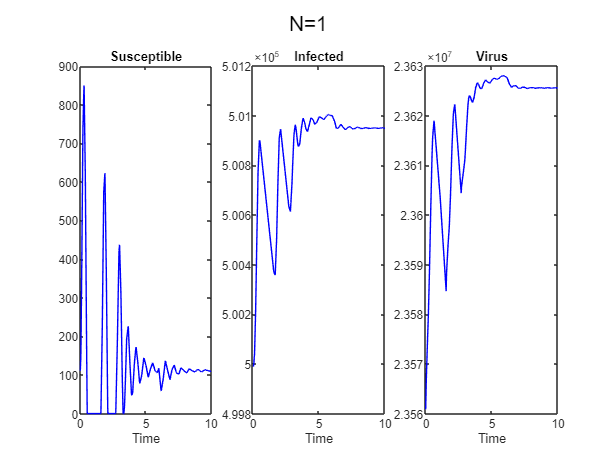

ymodel=gsua_eval(T.Nominal,T,0:0.01:10);%obtener los resultados al simular el modelo

T.Properties.CustomProperties.output = 1:3;
M=gsua_dmatrix(T,150);

Generating xdata and ynom values
Progress: 100%
Estimated processing time (h:m:s): 0:0:26
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:26
Estimated stop time (h:m:s): 21:28:58
Number of simulations: 150


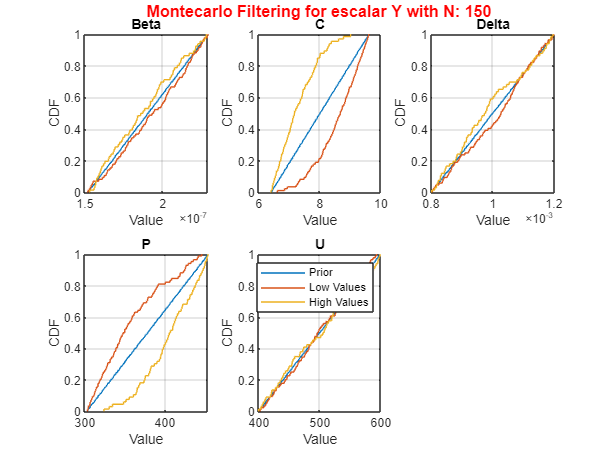

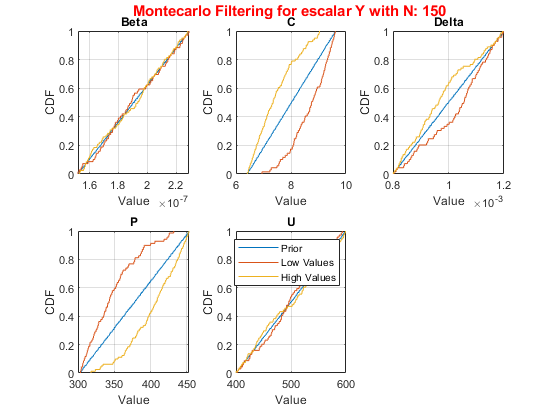

Y=gsua_ua(M,T,'parallel',false);